# UI編：MATLAB -> C++ -> WebAssembly の自動変換を使った非線形最適化 on JavaScript

## 0. はじめに

以前、WebAssembly を生成して MATLAB の `fmincon` をブラウザ上で実行する話を書きましたが、今回は UI 周りを作ってみたのでご紹介。

人前に出せるようなコードではない気もするんですが、折を見て徐々に改良したいのでヒントがあればぜひコメントください。宜しくお願い致します。

実行ページはこちら：Github Pages: [Rebalance Portfolio](https://minoue-xx.github.io/rebalance_portfolio/)

コードこちらから： GitHub: [minoue-xx/rebalance_portfolio](https://github.com/minoue-xx/rebalance_portfolio)

MATLAB -> WebAssembly の自動変換部分についてはこちらの記事を参照ください。

[Qiita: MATLAB -> C++ -> WebAssembly の自動変換を使った非線形最適化 on JavaScript](https://qiita.com/eigs/items/68cdcec7b8d56a5b440f)

## 1. 用途と使いかた

目的は一貫して

**「バランスが崩れた保有割合を目標割合に近づけるためには各銘柄を何株買えばいいのか」**

ということですが、選択肢は「買う」のみ。リバランスとは言うものの売ることは考えていません。積立向き？

以下、操作画面（GIF）です。

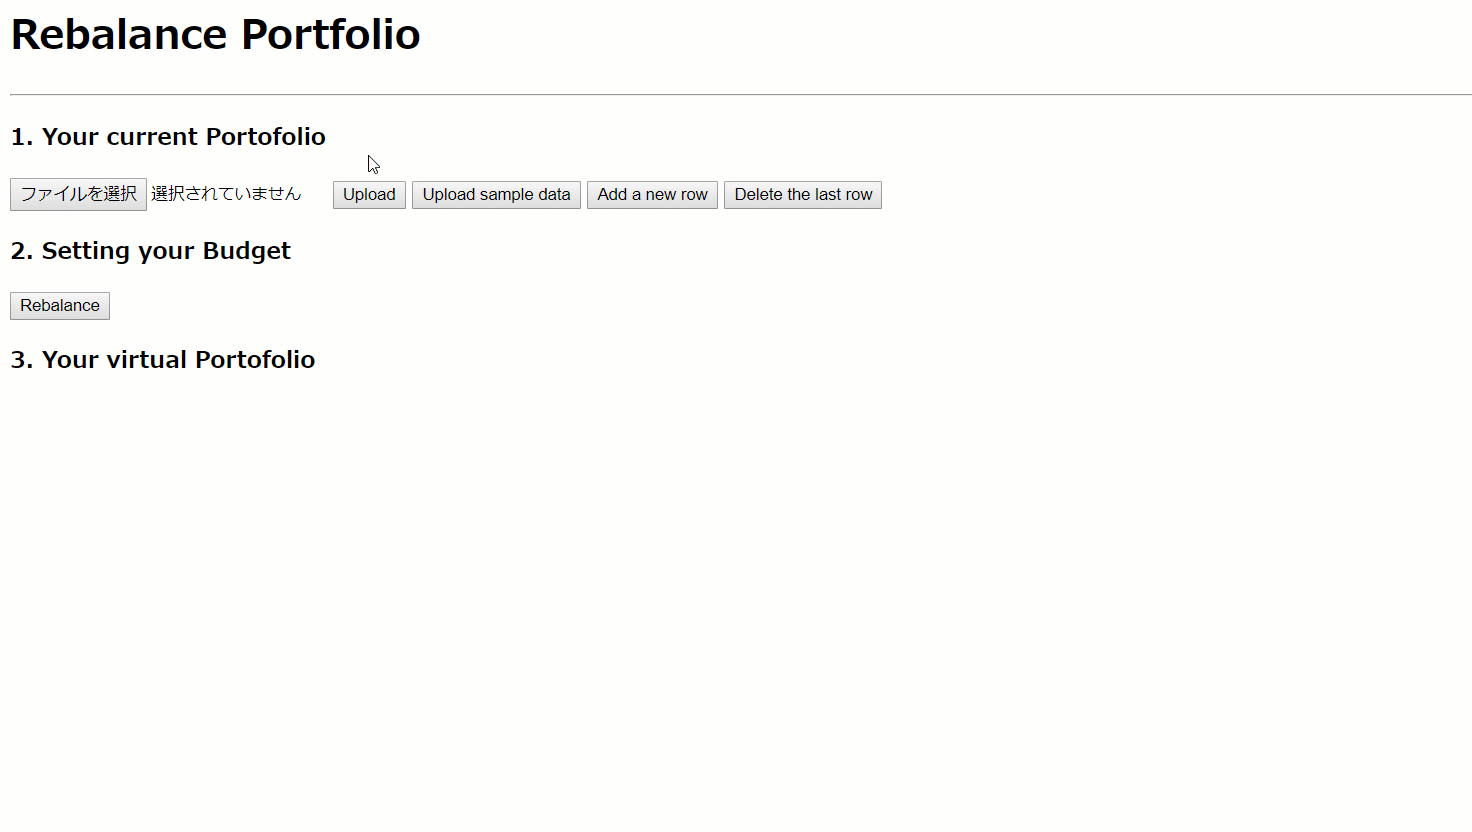

こんな感じ。

**Step 1: 現在のポートフォリオ表示**

保有銘柄・数は csv ファイルから読み込みます。試しにサンプルデータから開始してもよし。

現在価格や小計・合計・割合は自動計算します。必要があれば銘柄・保有数など変更してみてください。csv ファイルのフォーマットは以下の様にしてください。[Ticker],[保有数],[目標保有割合]の順。

**Step 2: 予算額入力**

使える額を入力して [Rebalance]ボタンをクリック。

**Step 3: 必要購入数を計算・結果表示**

Target% (目的の保有割合) に近づきましたね。

## 2. 使用した細かい要素について

JavaScript は初めてだったので検索しながら＋同僚にヒントをもらって構築しました。やっていることは基本的なことだと（？）思いますので、今回大変参考・勉強になった情報を並べておきます。**0.** [**Finantial Modeling Prep**](https://financialmodelingprep.com/)

無料＋認証不要という条件で探して、株価情報はここの API を使いました。

（無料API一覧：[https://github.com/public-apis/public-apis）](https://github.com/public-apis/public-apis%EF%BC%89)

1. [Qiita: letとvarの違い](https://qiita.com/y-temp4/items/289686fbdde896d22b5e)

まずはこれ。いろんな方のコードをコピペしたので、var と let が混在していました。let に統一する際に、知らなかったスコープの違いでエラーが起こるなどしていた際に参考になりました。

2. [Using jQuery to Perform Calculations in a Table](https://www.dotnetcurry.com/jquery/1189/jquery-table-calculate-sum-all-rows)

今回のページ構成のベースになっています。

3. [【jQuery入門】find()で子要素を取得する手法まとめ！](https://www.sejuku.net/blog/37474)

上を理解するのに助かりました。class属性であれば「. 」、id属性であれば「#」。

4. [Read CSV File in jQuery using HTML5 File API](https://www.aspsnippets.com/Articles/Read-CSV-File-in-jQuery-using-HTML5-File-API.aspx)

csv ファイルの読み込み部分は、ほぼこちらのコピペ。

5. [How to convert a currency string to a double with jQuery or Javascript? - Stack Overflow](https://stackoverflow.com/questions/559112/how-to-convert-a-currency-string-to-a-double-with-jquery-or-javascript)

金額の表示って結構面倒くさい。

を使わせてもらいました。

6. [How can I format numbers as currency string in JavaScript? - Stack Overflow](https://stackoverflow.com/questions/149055/how-can-i-format-numbers-as-currency-string-in-javascript)

金額表示から数値に戻す部分は以下で。

## 3. さいごに: WebAssembly 化した MATLAB コード

[Qiita: MATLAB -> C++ -> WebAssembly の自動変換を使った非線形最適化 on JavaScript](https://qiita.com/eigs/items/68cdcec7b8d56a5b440f)　で紹介したものとほぼ同じですが、

- `budget` 予算額（スカラー値）を入力として追加

- 初期値は予算額を目的保有割合で分配した値を使用

の2点を変更しています。結果が初期値に依存（局所解を出して）しまう点については、また書いてみます。

## Appendix: getPosition2Add.m

function xlong = getPosition2Add(target_pf, price, position, budget)

% Specify the Dimensions and Data Types
assert(isa(target_pf, 'double'));
assert(isa(price, 'double'));
assert(isa(position, 'double'));
assert(isa(budget, 'double'));
assert(all( size(target_pf) == [ 1, 10 ]))
assert(all( size(price) == [ 1, 10 ]))
assert(all( size(position) == [ 1, 10 ]))
assert(all( size(budget) == [ 1, 1 ]))


idx = target_pf > 0;
target_pf = target_pf(idx);
price = price(idx);
position = position(idx);
N = sum(idx);

% それぞれの銘柄いくつ購入すればターゲットとする保有割合に近づくかを求めます。
%　その際の制約は Cost：合計何ドルまでの購入とするか
Cost = budget(1);

% 線形不等式制約なし
A = [];
b = [];
% 線形等式制約（合計コストが Cost ）
% Aeq = [];
% beq = [];
Aeq = price;
beq = Cost;
% 購入数の上下限
lb = zeros(1,N);
ub = inf(1,N);
% 初期値は Cost を target_pf で割り振った際の値を使用
x0 = Cost*target_pf./(price);

options = optimoptions('fmincon','Algorithm','sqp');

% 目的関数は getDiff で定義されています。
% ターゲットの保有割合との誤差二乗和平方根を最小とすることを目指します。
objfun = @(x2add) getDiff(x2add,price,position,target_pf);
x = fmincon(objfun,x0,A,b,Aeq,beq,lb,ub,[],options);

% fmincon を使用
% 本来は整数問題ですが実数で株数を求めた後、端数は無視します。
% 購入株数が多ければそこまで問題にはならないため
% 購入株数の小数点以下切り捨て
xlong = zeros(1,10);
xlong(1:N) = floor(x);

end


function errorRMS = getDiff(position2add,marketvalue,position,target_pf)
newTotal = marketvalue.*(position2add+position);
newPF = newTotal/sum(newTotal);
errorRMS = sqrt(sum( (newPF - target_pf).^2 ) );
end